# Customize Bottom Border of Entry That Spans Multiple Columns

To customize the bottom border of an entry that spans multiple columns:

- Specify the bottom border of the entry that spans the columns. This specification determines the border that is shared with the entry in the next row that is in the first column of the span.

- In the next row, specify the top borders of the entries that are in the remaining columns of the span.

This example defines a table that has two rows and three columns. The entry in row one and column one spans three columns. To make the bottom border of this entry red along the entire span, the example specifies that:

- The bottom border of the row one, column one entry is red.

- The top borders of the row two, column two and row two, column three entries are red.

Create  a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myColSpanBorder.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Table");

Create a table that has three columns.

t = Table(3);
t.Style = [t.Style {VAlign("middleCentered")}];

Create the first row of the table.

tr1 = TableRow();

Create the first entry of the first row and specify that the entry spans three columns. Specify that the bottom border of the entry is red. Append the entry to the row.

te11 = TableEntry("entry 1,1");
te11.ColSpan = 3;
border = Border();
border.BottomColor = 'red';
te11.Style = [te11.Style {border}];
append(tr1,te11);

Create the second row of the table. 

tr2 = TableRow();

Create the first entry of the second row and append the entry to the row. The top border of this entry is determined by the bottom border of the row one, column one entry.

te21 = TableEntry("entry 2,1");
append(tr2,te21);

Create the second entry of the second row, specify that the top border is red, and append the entry to the row.

te22 = TableEntry("entry 2,2");
b = Border();
b.TopColor = 'red';
te22.Style = [te22.Style {b}];
append(tr2,te22);

Create the third entry of the second row, specify that the top border is red, and append the entry to the row.

te23 = TableEntry("entry 2,3");
b = Border();
b.TopColor = 'red';
te23.Style = [te23.Style {b}];
append(tr2,te23);

Append the rows to the table.

append(t,tr1);
append(t,tr2);

Add a title and the table to the slide.

replace(slide,"Title","Table Entry That Spans Multiple Columns");
replace(slide,"Table",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

The bottom border of the first row entry is red along the entire span.

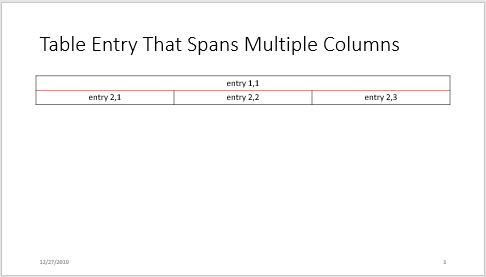

*Copyright 2019 The MathWorks, Inc.*